# Exercises 7.2

2. Solve the problem above using the Galerkin method with two basis functions. You may need symbolic manipulation software inorder to speed up your calculations.

clear all
clc
syms x
syms c1 c2

N1 = x*(x-1);
N2 = x*x*(x-1);
y  = @(x) c1*N1+c2*N2;
R  = @(x)diff((y(x)),2) + y(x) - 2*x;
w1 = N1;
w2 = N2;
A1 = int(R(x)*w1, 0, 1);
A2 = int(R(x)*w2, 0, 1);
A = solve ([A1 A2], [c1 c2]);
c1 = A.c1;
c2 = A.c2;
y  = @(x) c1*N1+c2*N2;
R  = @(x)diff((y(x)),2) + y(x) - 2*x;
yx = y(x)

$$yx = \frac{14\,x^{2}\,\left(x-1\right)}{41}+\frac{142\,x\,\left(x-1\right)}{369}$$

Rx = R(x)

$$Rx = \frac{2\,x}{41}+\frac{14\,x^{2}\,\left(x-1\right)}{41}+\frac{142\,x\,\left(x-1\right)}{369}+\frac{32}{369}$$

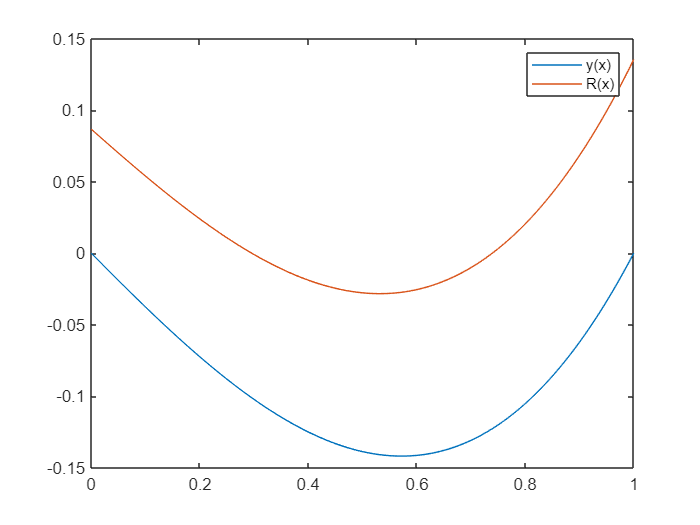

X = 0:0.01:1;
y = subs (yx,x, X);
R = subs (Rx,x, X);
plot(X,y,X,R)
legend ('y(x)','R(x)')